# Masking code

## Setup

addpath(genpath('Mesh_voxelisation'))
addpath(genpath('plane_line_intersect'))

### Calibrate the time errors

The ±error in mm for the position of the truck at the start frame:

err_frame_start =1

err_frame_start = 1

The width of the light sheet in mm:

err_lightsheet_width =2

err_lightsheet_width = 2

The ±error in mm for truck manufacturing tolerance:

err_truck_manufacturing =1

err_truck_manufacturing = 1

Error due to wobble in mm:

err_wobble =1

err_wobble = 1

### Set resolutions

Voxel size length in mm

VOXEL_SIDE_LENGTH =1

VOXEL_SIDE_LENGTH = 1

Mask pixel length is 1 mm

MASK_PIXEL_LENGTH = 1

MASK_PIXEL_LENGTH = 1

### Get our input data

Import the .stl file

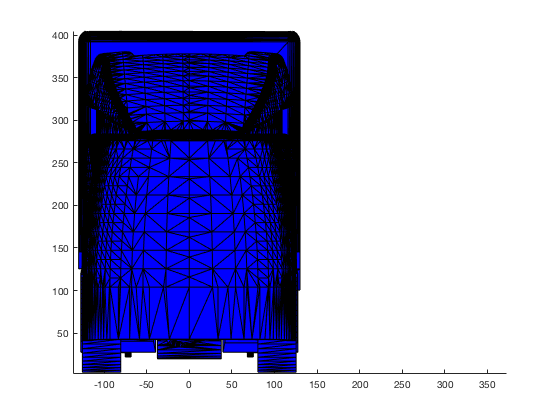

[stlcoords] = READ_stl('baselinelorrymodel.STL');
xco = squeeze( stlcoords(:,1,:) )';
xrange = max(xco,[],'all') - min(xco,[],'all');
yco = squeeze( stlcoords(:,2,:) )';
yrange = floor(max(yco,[],'all') - min(yco,[],'all'));
zco = squeeze( stlcoords(:,3,:) )';
zrange = floor(max(zco,[],'all') - min(zco,[],'all'));
[hpat] = patch(xco,yco,zco,'b');
axis equal


zscale = 2;

Voxelise the .stl model

%[OUTPUTgrid] = VOXELISE(floor(xrange),floor(yrange),floor(zrange*zscale),'baseline_round_w.STL','xyz');

Place the voxelised model in world coordinates

%model = flip(flip(OUTPUTgrid,3),1);
%save('voxelised.mat','model');
load('voxelised.mat','model');

#### Import the camera information

camera3_struct = load('camera3_calibration.mat','translationVector');
camera4_struct = load('camera4_calibration.mat','translationVector');
camera3 = camera3_struct.translationVector;
camera4 = camera4_struct.translationVector;
calibration_plate_thickness = 11.5;

camera3(:,1) = -camera3(:,1);
camera3(:,2) = -camera3(:,2);

camera4(:,2) = -camera4(:,2);
camera4(:,3) = -camera4(:,3) - calibration_plate_thickness;

## Slice into masks

slices = false([floor(xrange) floor(yrange) ceil(zrange)]);

for i=1:floor(zrange*zscale)
    slicenumber = floor((i+1)/zscale);
    frommodel = model(:,:,i);
    slices(:,:,slicenumber) = slices(:,:,slicenumber) | frommodel;
end

v = VideoWriter('smeared_masks_3.avi','Grayscale AVI');

open(v);
% almostframe = false([zrange yrange]);
% for n = 1:200
%     almostframe(n,:) = true([1 yrange]);
% end
% frame = mat2gray(almostframe);
% writeVideo(v,frame);
for i = 1:size(smearrr,3)
    frame = mat2gray(smearrr(:,:,i));
    writeVideo(v,frame);
end
close(v);

## Ray trace masks

%TODO
[visibility_matrices_3,visibility_matrices_4] = raytracealong(slices,camera3,camera4);


## Transform to final co-ordinate system

%TODO: read Isabel's code

## Smear and combine

### Smear in space

smear_mm = err_frame_start + err_lightsheet_width + err_truck_manufacturing + err_wobble

smear_mm = 5


spacesmeared_frontal = smear_space(visibility_matrices_3,smear_mm);
spacesmeared_back = smear_space(visibility_matrices_4,smear_mm);

### Smear across time (in frames)

smear_frames =5

mask_frontal = smear_time(spacesmeared_frontal,smear_frames);
mask_back = smear_time(spacesmeared_back,smear_frames);

### Combine

mask_and = mask_frontal & mask_back;
mask_or = mask_frontal | mask_back;

## Filter

For each frame, import data, apply the mask, and then output the cleaned frame file

%TODO

Done.